# Tutorial: OCT file reading

This tutorial shows how to:

- Load OCT files

- Visualize loaded data (fundus image, OCT slices, segmentation...)

If you need help please reach out at **dromero@mondragon.edu**

clc; clearvars; close all;
addpath(genpath('../retimat'));

#### Load .vol file

file = '../retimat/data/raster.vol';
[header, seg, bscan, fundus] = read_vol(file, 'get_coordinates');

#### Plot header

disp(header)

          fixation: 'macula'
     bscan_pattern: 'raster'
           n_ascan: 512
           n_bscan: 25
           n_axial: 496
           scale_x: 0.0124
           scale_y: 0.2650
           scale_z: 0.0039
     size_x_fundus: 768
     size_y_fundus: 768
    scale_x_fundus: 0.0124
    scale_y_fundus: 0.0124
        fov_fundus: 30
        patient_id: 'E01'
               eye: 'OD'
        scan_focus: -4.6375
             X_fun: [768×768 double]
             Y_fun: [768×768 double]
             X_oct: [25×512 double]
             Y_oct: [25×512 double]



#### Segmented layers

layers = fields(seg);
disp(layers')

    {'ILM'}    {'BM'}    {'RNFL_GCL'}    {'GCL_IPL'}    {'IPL_INL'}    {'INL_OPL'}    {'OPL_ONL'}    {'ELM'}    {'MZ_EZ'}    {'OSP_IZ'}    {'IZ_RPE'}



#### Visualize fundus image (slo)

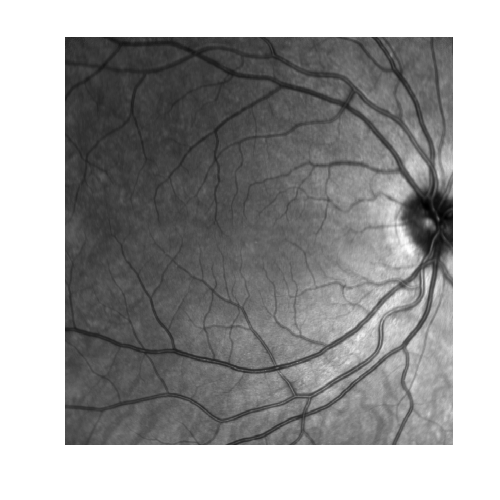

f = figure('Position',[0 0 400 400]);
imagesc(fundus); colormap(gray); axis("off");

#### Visualize OCT slices

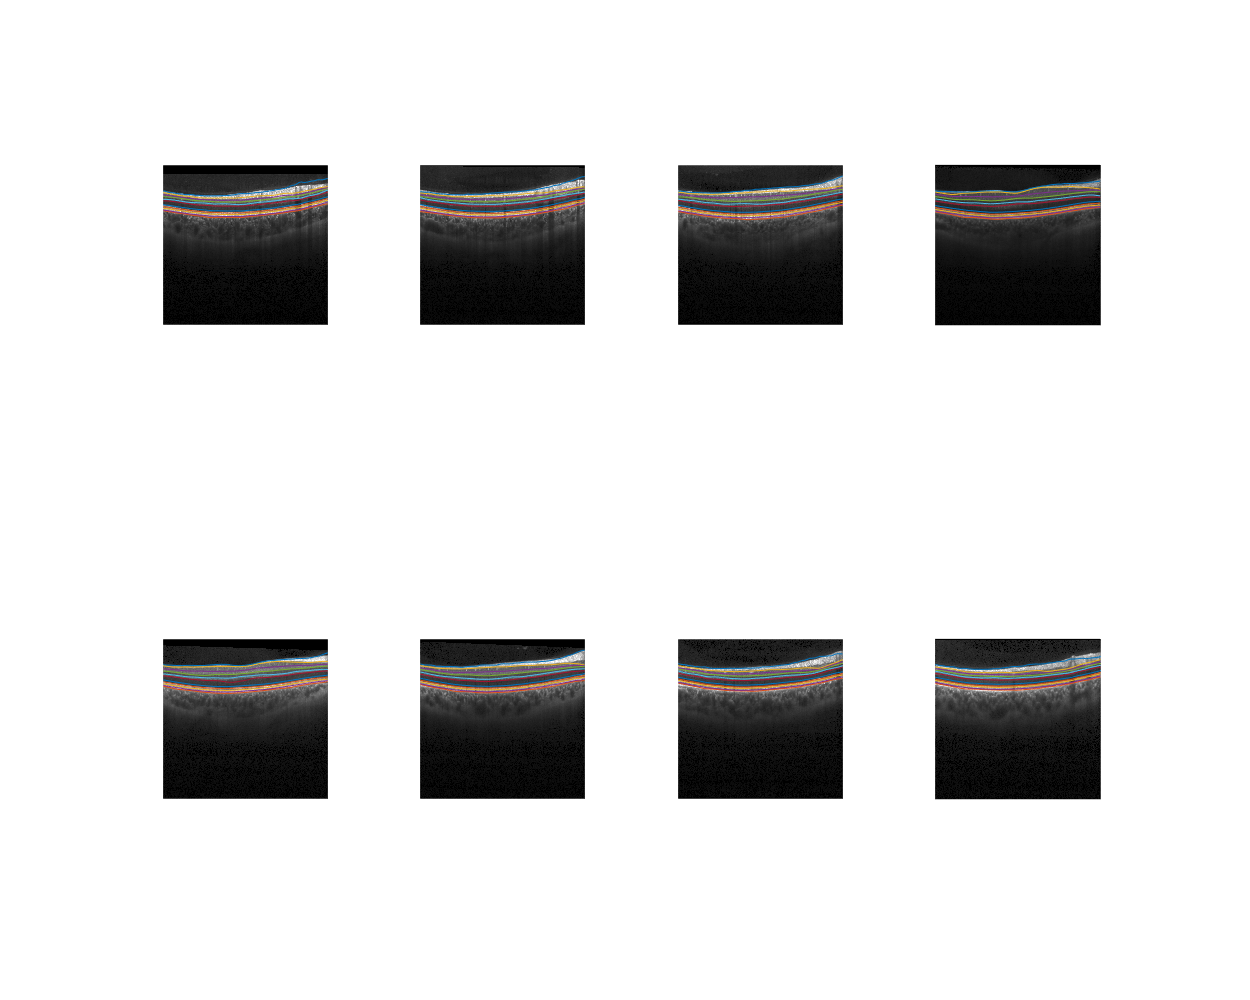

f = figure('Position',[0 0 1000 800]);
idx_bscan = round(linspace(1, 25, 8));
for i=1:length(idx_bscan)
    subplot(2,4,i); hold on;
    imshow(bscan(:,:,idx_bscan(i)));
    for i_layer=1:length(layers)
        layer = layers{i_layer};
        plot(seg.(layer)(idx_bscan(i), :))
    end
end